## find bracket

function isBracket = test_bracket(f,a,b,c)
    isBracket = f(b)<f(a) && f(b)<f(c);
end

function [n,a,b,c] = find_bracket(f)
    phi = 0.618;
    n = 0;
    a = (1 + phi)^(n);
    b = (1 + phi)^(n + 1);
    c = (1 + phi)^(n + 2);

    while ~test_bracket(f, a, b, c)
        a = a * (1 + phi);
        b = b * (1 + phi);
        c = c * (1 + phi);
        n = n + 1;
    end
end

## interpolation

function [parabola,a,b,c,z] = golden_section_interp(f,a0,b0,c0,steps)
    a = a0;
    b = b0;
    c = c0;
    
    s = 0;

    % I: s = index of last computed a,b,c, 
    % alpha beta gamma z parabola are not yet computed
    
    while true
        fa = f(a); fb = f(b); fc = f(c);
        alpha = fa/(a-b)/(a-c);
        beta = fb/(b-a)/(b-c);
        gamma = fc/(c-a)/(c-b);

        parabola = @(x) alpha*(x-b)*(x-c) + beta*(x-a)*(x-c) + gamma*(x-a)*(x-b);
        z = (alpha*(b+c)+beta*(a+c)+gamma*(a+b))/2/(alpha+beta+gamma);
        fz = f(z);

        if s==steps
            break;
        end

        if z>b
            if fz<fb
                a = b;
                b = z;
            else
                c = z;
            end
        else
            if fz<fb
                c = b;
                b = z;
            else
                a = z;
            end
        end

        s = s+1;
    end
    %fprintf("After %d steps, b = %d\n", steps, b);
end

function [n,a,b,c,z] = golden_section_search(f,a0,b0,c0,N,tol)
    a = a0;
    b = b0;
    c = c0;
    
    s = 0;

    % I: s = index of last computed a,b,c, 
    % alpha beta gamma z parabola are not yet computed
    
    while true
        fa = f(a); fb = f(b); fc = f(c);
        alpha = fa/(a-b)/(a-c);
        beta = fb/(b-a)/(b-c);
        gamma = fc/(c-a)/(c-b);

        z = (alpha*(b+c)+beta*(a+c)+gamma*(a+b))/2/(alpha+beta+gamma);
        fz = f(z);

        if s==N
            fprintf("did not converge");
            break;
        end

        if abs(c-a)<tol*(1+abs(b))
            break;
        end

        if z>b
            if fz<fb
                a = b;
                b = z;
            else
                c = z;
            end
        else
            if fz<fb
                c = b;
                b = z;
            else
                a = z;
            end
        end

        s = s+1;
    end
    n=s;
end

## plotting function

function plot_bracket(ax,f,a,b,c,xmin,xmax)
    %hold on;
    density = 100;
    range = xmax - xmin;
    x = linspace(xmin, xmax, density * range);
    y = arrayfun(f, x);
    plot(ax,x, y, '-b');

    scatter(ax,[a b c], [f(a) f(b) f(c)], '.r');

    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
end

function plot_parabola(ax,p,xmin,xmax)
    %hold on;
    density = 100;
    xs = linspace(xmin,xmax,(xmax-xmin)*density);
    ys = arrayfun(p,xs);
    plot(ax,xs,ys,'--k','LineWidth',3);
end

function m = plot_gs(ax,f,a0,b0,c0,steps,xmin,xmax)
    %hold on;
    [parabola, a,b,c,z] = golden_section_interp(f,a0,b0,c0,steps);
    fprintf("a: %f, b:%f, c:%f, z:%f\n",a,b,c,z);
    
    plot_bracket(ax,f,a,b,c,xmin,xmax);
    plot_parabola(ax,parabola,xmin,xmax);
    plot(ax,z,f(z),'.g','MarkerSize',15);
    plot(ax,z,parabola(z),'.k');
    m = b;
end

function update_plot(ans_lbl,ax,f,a0,b0,c0,steps,xmin,xmax)
    %clf; cla;
    cla(ax); 
    hold(ax,'on');
    m = plot_gs(ax,f,a0,b0,c0,steps,xmin,xmax);
    title(ax, ['Iteration: ', num2str(steps)]);
    ans_lbl.Text = "Ans: "+num2str(m);
    grid(ax, 'on');
    hold(ax, 'off');
end

## Driver

f = @(x) 1/(1-x)/(2-x)/(1+x)/(2+x);
f = @(x) -(x^2)

f = function_handle with value:
    @(x)-(x^2)




a0 = 0;
b0 = 1;
c0 = 2;
a0=-2.5;b0=-1.5;c0=0.5;
%[n,a0,b0,c0] = find_bracket(f);

xmin = -2;
xmax = 2;
steps =25;

ax = gca;
cla(ax);
hold(ax,'on');

plot_gs(ax,f,a0,b0,c0,steps,xmin,xmax);

a: -2.500000, b:-1.500000, c:-0.000000, z:-0.000000


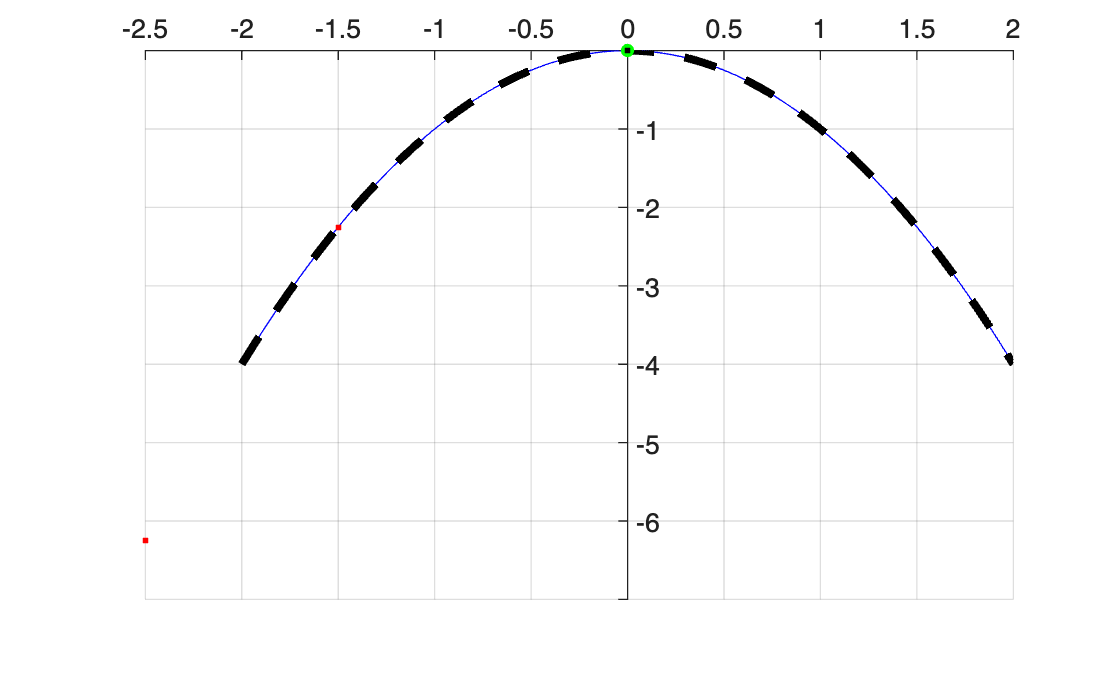


hold(ax,'off');
grid on;


[n,aa,bb,cc,zz] = golden_section_search(f,a0,b0,c0,1000,3e-7);

did not converge

n

n = 1000

aa

aa = -2.5000

bb

bb = -1.5000

cc

cc = 0

zz

zz = 0